# PHY 329 Homework 5

## Ryan Schlimme (eid: rjs4499)

# Problem 22.1

Solve the IVP from t = 0 with y(0) = 1.

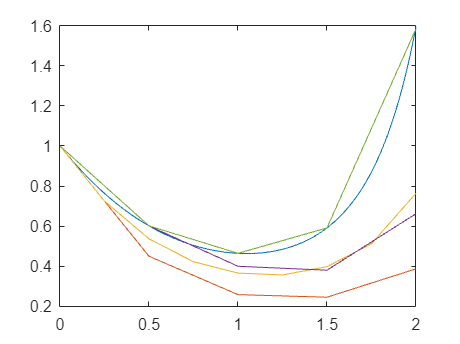

dydt = @(t,y) y*t.^2 - 1.1*y;

[t,y] = eulode(dydt, [0,2], 1, 0.5);
[t1,y1] = eulode(dydt, [0,2], 1, 0.25);
[t2,y2] = eulmidode(dydt, [0,2], 1, 0.50);
[t3,y3] = rk4(dydt, [0,2], 1, 0.5);

exact = @(t) exp(t.^3 / 3 - 1.1*t);

ts = linspace(0,2,1000);

figure(1);plot(ts,exact(ts),t,y,t1,y1, t2, y2, t3, y3)

# Problem 22.3

Solve the IVP over the interval t = 0 to t = 3 using step size h = 0.5 with y(0) = 1.

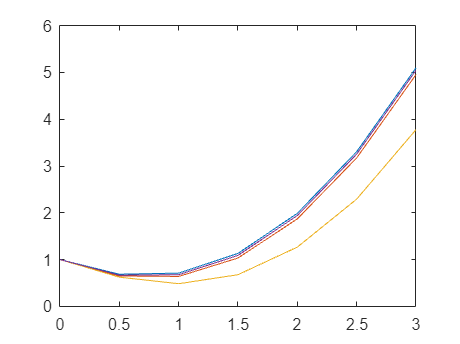

dydt = @(t,y) -y+t.^2;

% Heun w/o iterating corrector
[t1,y1] = heunNO(dydt, [0,3], 1, 0.5);
% Heun until error < 0.1&
[t2,y2] = heun(dydt, [0,3], 1, 0.5, 0.01);
% midpoint
[t3,y3] = eulmidode(dydt, [0,3], 1, 0.5);
% Ralston
[t4,y4] = ralston(dydt, [0,3], 1, 0.5);

exact = @(t) exp(1/3*t.^3);

ts = linspace(0,3,1000);

figure(2);plot(t1, y1, t2, y2, t3, y3, t4, y4);

# Problem 22.6

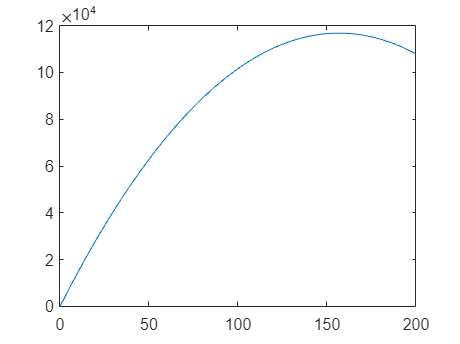

R = 6.37e6;
dxdt = @(t,x,v) v;
dvdt = @(t,x,v) -9.81*R^2/(R+x).^2;

[t,x,v] = rk4sys(dxdt, dvdt, [0,200], 0, 1500, 0.5);

figure(3);plot(t,x)


max(x) % 116.78 km

ans = 1.1678e+05

# Problem 22.7

Solve the pair of ODE's from t = 0 to t = 0.4 using h = 0.1. y(0) = 2, z(0) = 4.

## Part a) Euler's Method

dydt = @(t,y,z) -2*y+4*exp(-t);
dzdt = @(t,y,z) -y*z.^2 /3;

[t1,y1,z1] = eulersys(dydt, dzdt, [0,0.4], 2, 4, 0.1);

## Part b) Fourth Order RK Method

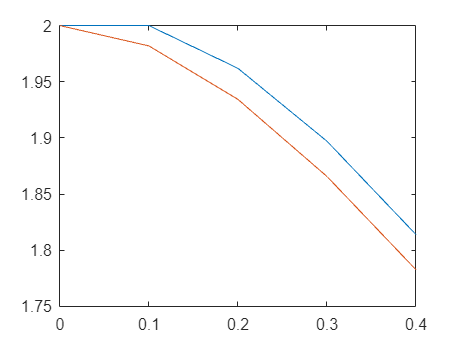

dydt = @(t,y,z) -2*y+4*exp(-t);
dzdt = @(t,y,z) -y*z.^2 /3;

[t2,y2,z2] = rk4sys(dydt, dzdt, [0,0.4], 2, 4, 0.1);

figure(5);plot(t1,y1,t2,y2)

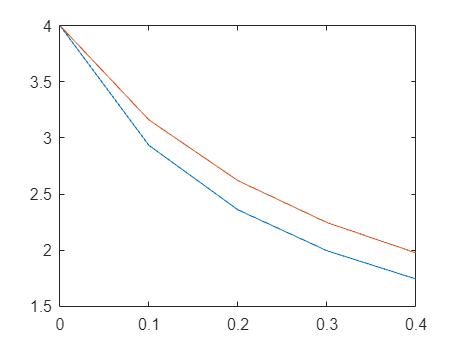

figure(6);plot(t1,z1,t2,z2)

# Problem 22.15

Solve a second order ODE with m = 20 kg, c = 5,40,200. k = 20. dx/dt(0) = 0. x(0) = 1. Solve over time interval 0 to 15 s. Plot displacement vs time for each value of c.

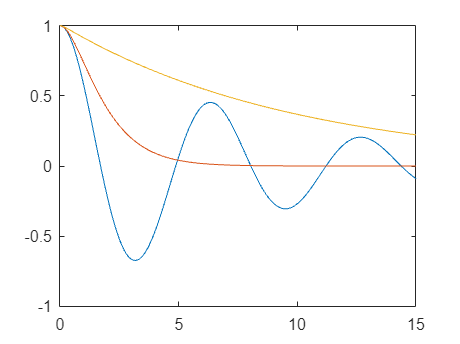

m = 20; k = 20;

c1 = 5;
c2 = 40;
c3 = 200;

dxdt = @(t,x,v) v;
dvdt1 = @(t,x,v) (-c1*v-k*x)/m;
dvdt2 = @(t,x,v) (-c2*v-k*x)/m;
dvdt3 = @(t,x,v) (-c3*v-k*x)/m;

[t1,x1,v1] = rk4sys(dxdt, dvdt1, [0,15], 1, 0, 0.1);
[t2,x2,v2] = rk4sys(dxdt, dvdt2, [0,15], 1, 0, 0.1);
[t3,x3,v3] = rk4sys(dxdt, dvdt3, [0,15], 1, 0, 0.1);

figure(7);plot(t1,x1,t2,x2,t3,x3)

# Problem 22.19

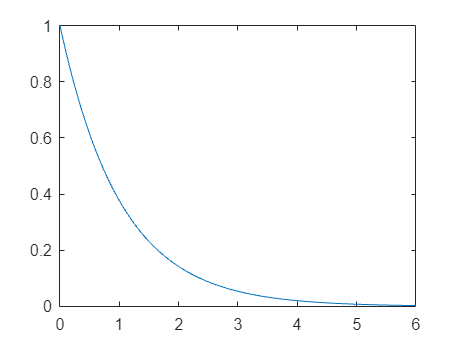

dCdt = @(t,C,T) -exp(-10/(T+273))*C;
dTdt = @(t,C,T) 1000*exp(-10/(T+273))*C-10*(T-20);

[t5,c1,T1] = eulersys(dCdt, dTdt, [0,6], 1, 15, 0.01);

figure(10);plot(t5,c1)

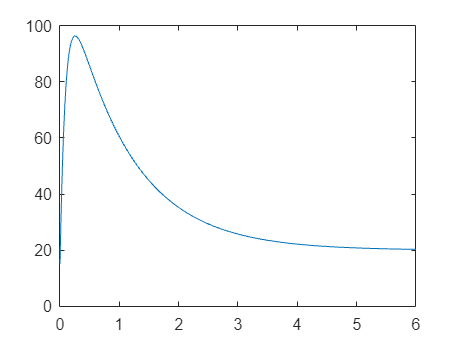

figure(11);plot(t5,T1)

# Problem 22.20

Calculate deflection y if y(0) = 0, dy/dz(0)=0. L = 30, E = 1.25e8, I = 0.05.

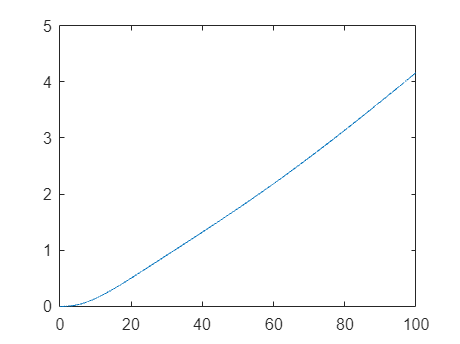

L = 30; E = 1.25e8; I = 0.05;

dydz = @(z,y,w) w;
dwdz = @(z,y,w) (((200*z)/(5+z))*exp(-2*z/30))/(2*E*I)*(L-z).^2;

[t10,y10,w10] = rk4sys(dydz, dwdz, [0,100], 0, 0, 0.01);

figure(12);plot(t10,y10)

# Define Our Functions

% Euler's Method

function [t,y]=eulode(dydt, tspan, y0, h, varargin)
if nargin<4, error("at least 4 inputs required"), end
ti = tspan(1);tf = tspan(2);
if ~(tf>ti), error('upper limit must be greater than lower'), end
t = (ti:h:tf)'; n = length(t);
if t(n)<tf
    t(n+1) = tf;
    n = n + 1;
end
y = y0*ones(n,1);
for i = 1:n-1
    y(i+1) = y(i) + dydt(t(i),y(i),varargin{:})*(t(i+1)-t(i));
end
end

% Euler's Midpoint
function [t,y]=eulmidode(dydt, tspan, y0, h, varargin)
if nargin<4, error("at least 4 inputs required"), end
ti = tspan(1);tf = tspan(2);
if ~(tf>ti), error('upper limit must be greater than lower'), end
t = (ti:h:tf)'; z = diff(t); n = length(t);
if t(n)<tf
    t(n+1) = tf;
    n = n + 1;
end
y = y0*ones(n,1);
for i = 1:n-1
    y(i+1) = y(i) + dydt(t(i),y(i)+dydt(t(i),y(i))*h/2,varargin{:})*h;
end
end

% Heun's Method
function [t,y]=heun(dydt, tspan, y0, h, es, varargin)
if nargin<4, error("at least 4 inputs required"), end
ti = tspan(1);tf = tspan(2);
if ~(tf>ti), error('upper limit must be greater than lower'), end
t = (ti:h:tf)'; n = length(t);
if t(n)<tf
    t(n+1) = tf;
    n = n + 1;
end
y = y0*ones(n,1);
for i = 1:n-1
    y(i+1) = y(i) + dydt(t(i),y(i),varargin{:})*h;
    while 1
        z = y(i+1);
        y(i+1) = y(i) + (dydt(t(i),y(i),varargin{:})+dydt(t(i+1), z, varargin{:}))/2*h;
        ea = abs((y(i+1)-z)/y(i+1))*100;
        if ea <= es, break, end
    end
end
end

% Heun Non-Iterative
function [t,y]=heunNO(dydt, tspan, y0, h, varargin)
if nargin<4, error("at least 4 inputs required"), end
ti = tspan(1);tf = tspan(2);
if ~(tf>ti), error('upper limit must be greater than lower'), end
t = (ti:h:tf)'; n = length(t);
if t(n)<tf
    t(n+1) = tf;
    n = n + 1;
end
y = y0*ones(n,1);
for i = 1:n-1
    k1 = dydt(t(i), y(i));
    k2 = dydt(t(i)+h, y(i)+k1*h);
    y(i+1) = y(i) + (0.5*k1+0.5*k2)*h;
end
end

% Ralston's Method
function [t,y]=ralston(dydt, tspan, y0, h, varargin)
if nargin<4, error("at least 4 inputs required"), end
ti = tspan(1);tf = tspan(2);
if ~(tf>ti), error('upper limit must be greater than lower'), end
t = (ti:h:tf)'; n = length(t);
if t(n)<tf
    t(n+1) = tf;
    n = n + 1;
end
y = y0*ones(n,1);
for i = 1:n-1
    k1 = dydt(t(i), y(i));
    k2 = dydt(t(i)+2/3*h, y(i)+2/3*k1*h);
    y(i+1) = y(i) + (0.25*k1+0.75*k2)*h;
end
end

% Euler's Method System
function [t,x,y]=eulersys(e, f, tspan, x0, y0, h, varargin)
if nargin<4, error("at least 4 inputs required"), end
ti = tspan(1);tf = tspan(2);
if ~(tf>ti), error('upper limit must be greater than lower'), end
t = (ti:h:tf)'; n = length(t);
if t(n)<tf
    t(n+1) = tf;
    n = n + 1;
end
y = y0*ones(n,1);
x = x0*ones(n,1);
for i = 1:n-1
    x(i+1) = x(i) + e(t(i), x(i), y(i))*h;
    y(i+1) = y(i) + f(t(i), x(i), y(i))*h;
end
end

% Fourth-Order RK
function [t,y] = rk4(dydt, tspan, y0, h, varargin)
ti = tspan(1);tf = tspan(2);
if ~(tf>ti), error('upper limit must be greater than lower'), end
t = (ti:h:tf)'; n = length(t);
if t(n)<tf
    t(n+1) = tf;
    n = n + 1;
end
y = y0*ones(n,1);
for i = 1:n-1
    k1 = dydt(t(i),y(i));
    k2 = dydt(t(i)+0.5*h, y(i)+0.5*k1*h);
    k3 = dydt(t(i)+0.5*h, y(i)+0.5*k2*h);
    k4 = dydt(t(i)+h, y(i)+k3*h);
    y(i+1) = y(i) + 1/6*(k1+2*k2+2*k3+k4)*h;
end
end

% Fourth-RK System
function [t,x,y] = rk4sys(e, f, tspan, x0, y0, h, varargin)
ti = tspan(1);tf = tspan(2);
if ~(tf>ti), error('upper limit must be greater than lower'), end
t = (ti:h:tf)'; n = length(t);
if t(n)<tf
    t(n+1) = tf;
    n = n + 1;
end
y = y0*ones(n,1);
x = x0*ones(n,1);
for i = 1:n-1
    k1 = e(t(i),x(i),y(i));
    l1 = f(t(i),x(i), y(i));
    k2 = e(t(i)+0.5*h, x(i)+0.5*k1*h, y(i)+0.5*l1*h);
    l2 = f(t(i)+0.5*h, x(i)+0.5*k1*h, y(i)+0.5*l1*h);
    k3 = e(t(i)+0.5*h, x(i)+0.5*k2*h, y(i)+0.5*l2*h);
    l3 = f(t(i)+0.5*h, x(i)+0.5*k2*h, y(i)+0.5*l2*h);
    k4 = e(t(i)+h, x(i)+k3*h, y(i)+l3*h);
    l4 = f(t(i)+h, x(i)+k3*h, y(i)+l3*h);
    x(i+1) = x(i) + 1/6*(k1+2*k2+2*k3+k4)*h;
    y(i+1) = y(i) + 1/6*(l1+2*l2+2*l3+l4)*h;
end
end